# Toy model for carbon diffusion and graphite formation

% Isothermal condition
% Isotropic condition
numx = 1001;   %number of grid points in x (1000micron=1mm)
numt = 100000;  %number of time steps to be iterated-0.015 years
dx = 0.001/(numx - 1);% grid unit sizes-1micron
dt = 0.5;%unit time-1sec
x = 0:dx:0.001;   %vector of x values,from 1micron to 1mm

%specify initial conditions
t(1) = 0;      %t=0
C12= zeros(numx,numt);
C12(:,1)=1.3;
C12(1:3)=95;
C13= zeros(numx,numt); % preallocating for better utility, (when over 10^6 must do peicewise)
C13(:,1)=1.3*0.0112372;
C13(1:3)=95*0.0112372;
K=95/1.8; %partition coefficient
D1=1e-19;
D2=1e-12;
ratio=0.9228387;  %12C/13C mass ratio
Q=ratio^0.225; %Mueller.et.al 2014 mass fractionation kinetic factor
d1=D1*Q;
d2=D2*Q;
%R=1e-6;
step(1)=5000;
for k=2:45
    if k<12
    step(k)=step(k-1)+(k*2500); %accerating growth rate of crsytal using a incremental step function    
    else
    step(k)=step(k-1)+(10*2500); % constant growth rate after 10microns of graphite
    end
end
k=4;
%Cm13=zeros(numx,length(step));
%Cm12=zeros(numx,length(step));
   %initialize everything to zero

## Algorithm based on non-equilibrium Direct crystal separation, in a isothermal-linear acceleration crystallisation, using finite difference method on 2nd order Fick's equation.

%C12=1.80005;
f=linspace(1,0,step(k-3));%batch crystaliisation fraction on step sizes
b=1;%counter for the batch crystaliisation fraction indexing
%iterate difference equations
for j=1:numt
   
   %t(j+1) = t(j) + dt;
   for i=2:numx-1
       if i<k
            C12(i,j+1) = C12(i,j) + D1*(dt/dx^2)*(C12(i+1,j) - 2*C12(i,j) + C12(i-1,j)); 
       end
       if i==k
            C12(i,j+1) = C12(i,j) + D1*(dt/dx^2)*(C12(i-1,j) - C12(i,j))+(C12(i+1,j)*K*0.01);
       end
       if i==(k+1)
            C12(i,j+1) = C12(i,j) + D2*(dt/dx^2)*(C12(i+1,j) - C12(i,j))-(C12(i,j)*K*0.01);
       end
       if i>(k+1)
            C12(i,j+1) = C12(i,j) + D2*(dt/dx^2)*(C12(i+1,j) - 2*C12(i,j) + C12(i-1,j));
       end
   end
   for i=2:numx-1
       if i<k
            C13(i,j+1) = C13(i,j) + d1*(dt/dx^2)*(C13(i+1,j) - 2*C13(i,j) + C13(i-1,j)); 
       end
       if i==k
            C13(i,j+1) = C13(i,j) + d1*(dt/dx^2)*(C13(i-1,j) - C13(i,j))+(C13(i+1,j)*K*0.01);
       end
       if i==(k+1)
            C13(i,j+1) = C13(i,j) + d2*(dt/dx^2)*(C13(i+1,j) - C13(i,j))-(C13(i,j)*K*0.01);
       end
       if i>(k+1)
            C13(i,j+1) = C13(i,j) + d2*(dt/dx^2)*(C13(i+1,j) - 2*C13(i,j) + C13(i-1,j));
       end       
   end
   b=b+1;
   if mod(j,step(k-3))==0
       Cm13(:,k-3)=C13(:,step(k-3)-1);
       Cm12(:,k-3)=C12(:,step(k-3)-1);
       k=k+1;
       %C0=C(k,j);    
%        f=linspace(1,0,step(k-3));
%        b=1;
       %if k==9
           %break;
       %end
       %step=step+13000;% deccelerating growth rate
       %C(k,j+1)=(K+1)*C(k+1,j);
   end
   C12(1,j+1) = C12(2,j+1);          %C(1,j+1) found from no-flux condition
   C12(numx,j+1) = C12(numx-1,j+1);  %C(numx,j+1) found from no-flux condition
   C13(1,j+1) = C13(2,j+1);          %C(1,j+1) found from no-flux condition
   C13(numx,j+1) = C13(numx-1,j+1);  %C(numx,j+1) found from no-flux condition
if j>2
   s12 = sum(C12(1:numx-1,j))*0.1-sum(C12(1:numx-1,j-1))*0.1;% simple simpson integral
   s13 = sum(C13(1:numx-1,j))*0.1-sum(C13(1:numx-1,j-1))*0.1;
   if s12>1 || s13>0.1 %checking the integral for mass conservation at 0.1 error margin allowance
   disp("error in mass transfer")
   break;
   end
end
% if j>4
% C12(:,j-4)=[];
% end
% j
% k
end
C=C13./C12

C =     0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110
    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0

%CmC=Cm13./Cm12; %isotope ratio


%  CmC=C(:,step-1);
%save('testcl25_old','C12','C13','C','step','-v7.3');
%save('testcl25_1','Cm12','Cm13','CmC','step','-v7.3');

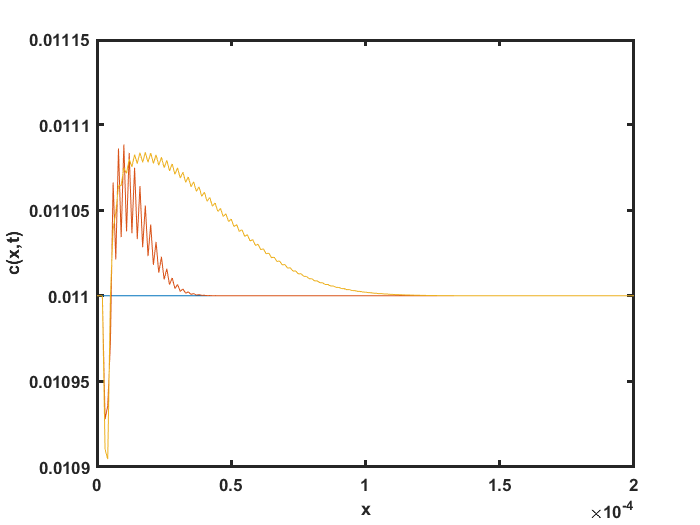


%figure(1);
%for j=1:numt

%plot(x,C(1:end-1,j),"LineWidth",2);
plot(x,C(1:end,1));
hold on
axis([0,0.0002,0.0109,0.01115]);
plot(x,C(1:end,100));
plot(x,C(1:end,1000));
plot(x,C(1:end,2000));
plot(x,C(1:end,4000));
plot(x,C(1:end,7000));
plot(x,C(1:end,10000));
% plot(x,C(1:end,20000));
% plot(x,C(1:end,30000));
% plot(x,C(1:end,40000));
% plot(x,C(1:end,80000));
% plot(x,C(1:end,100000));
% plot(x,C(1:end,200000));
% plot(x,C(1:end,300000));
h=gca;

h.YLimMode='manual';
h.FontSize=10;
h.FontWeight="bold";
h.LineWidth=1.8;
xlabel('x');
ylabel('c(x,t)');
%title(sprintf("Time:%d",j))


drawnow;
hold off


%end



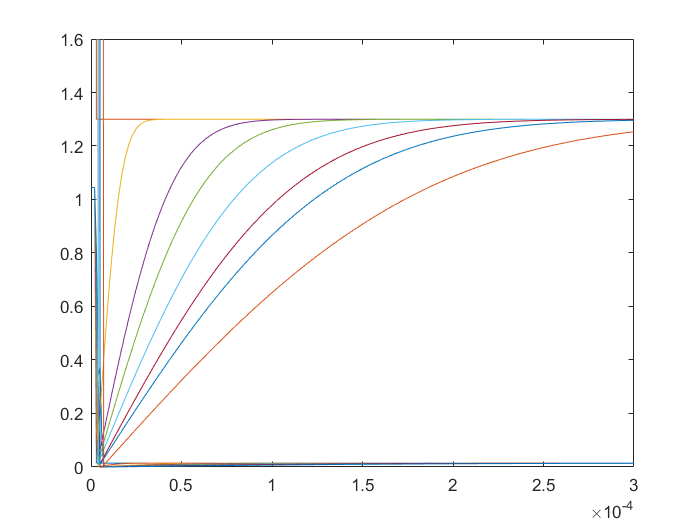

plot(x,C12(1:end,1));
hold on
axis([0,0.0003,0,1.6]);
plot(x,C12(1:end,100));
plot(x,C12(1:end,1000));
plot(x,C12(1:end,2000));
plot(x,C12(1:end,4000));
plot(x,C12(1:end,7000));
plot(x,C12(1:end,10000));
plot(x,C12(1:end,20000));
hold off

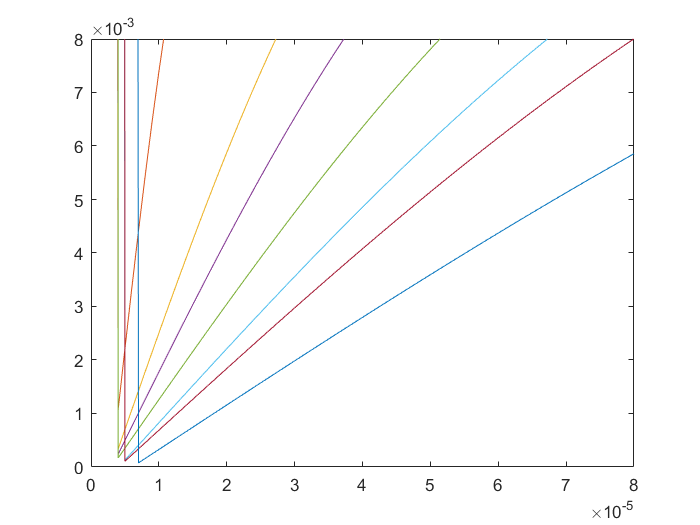

plot(x,C13(1:end,1));
hold on
axis([0,0.00008,0,0.008]);
plot(x,C13(1:end,100));
plot(x,C13(1:end,1000));
plot(x,C13(1:end,2000));
plot(x,C13(1:end,4000));
plot(x,C13(1:end,7000));
plot(x,C13(1:end,10000));
plot(x,C13(1:end,20000));
hold off